Задача №1

Рассчитать   и   построить   ВАХ   идеализированного   кремниевого   диода   в   пределахизменения  напряжения  от-5  до  +0.7  В  при  Т=300К  и  обратном  токе  насыщения,  равном $I_0$.Значение теплового потенциала $\varphi_T =\frac{\mathrm{kT}}{q}$ при Т=300К принять равным 0.026 В.

Определить дифференциальное $r_{\mathrm{dif}}$ и статическое сопротивление $d_0$ диода для заданногозначения $U_{\mathrm{пр}}$

Исходные данные:

$I_0 =0\ldotp 5e-9\;А$; 

$U_{\mathrm{пр}} =0\ldotp 35\;В$;

I_0 = 0.5e-9; %А
U_pr1 = 0.35; %В
fi_T = 0.026; %В
I = @(U) I_0.*(exp(U./fi_T)-1);

Задаем вектор значений $U_{\mathrm{обр}}$

U_obr = [-5 -1 -0.2 -0.1 -0.05 0]

U_obr =    -5.0000   -1.0000   -0.2000   -0.1000   -0.0500         0


Расчитываем вектор значений $I_{\mathrm{обр}}$ относительно $U_{\mathrm{обр}}$

I_obr = I(U_obr)

I_obr = 	1.0e+-9 *

   -0.5000   -0.5000   -0.4998   -0.4893   -0.4269         0


Строим ВАХ обратной ветви

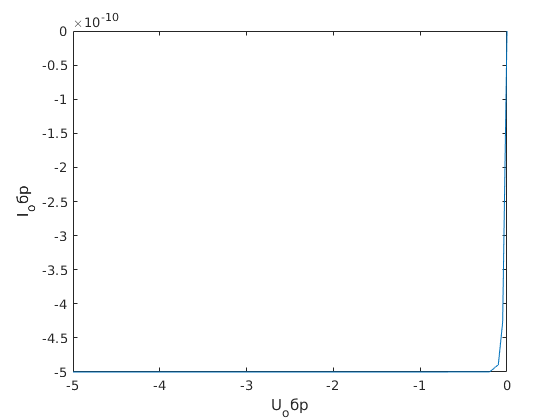

plot(U_obr,I(U_obr))
xlabel('U_обр');
ylabel('I_обр');

Задаем вектор значений $U_{\mathrm{пр}}$

U_pr = [0 .5 .55 .6 .62 .64 .66 .68 .7]

U_pr =          0    0.5000    0.5500    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000


Расчитываем вектор значений $I_{\mathrm{пр}}$ относительно $U_{\mathrm{пр}}$

I_pr = I(U_pr)

I_pr =          0    0.1124    0.7691    5.2620   11.3559   24.5073   52.8894  114.1408  246.3280


Строим ВАХ прямой ветви

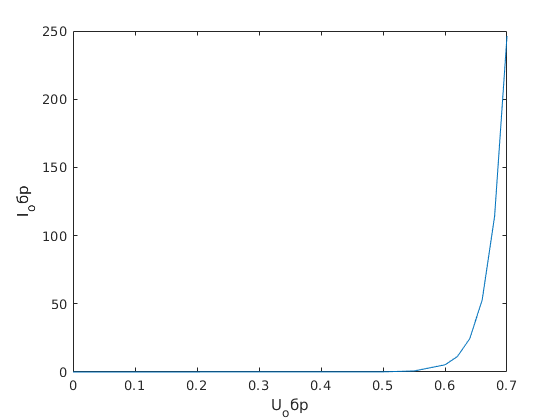

plot(U_pr,I(U_pr))
xlabel('U_обр');
ylabel('I_обр');

Расчитываем $R_{\mathrm{dif}}$

R_dif = fi_T/(I_0+I(U_pr1)) %Ом

R_dif = 74.0852

Расчитываем $R_0$

R_0 = U_pr1/I(U_pr1) %Ом

R_0 = 997.3022

Сравниваем $R_0$ > $R_{\mathrm{dif}}$

R_0 > R_dif

ans = logical
   1


Получаем логическую единицу, что соответствует правильному ответу.

Задача №2

Стабилитрон подключен для стабилизации напряжения параллельно резистору нагрузки $R_Н$. Параметры стабилитрона $U_{\mathrm{ст}}$,$I_{\textrm{ст}\ldotp \min }$,$I_{\textrm{ст}\ldotp \max }$ и сопротивление нагрузки $R_Н$ приведены в табл. 1.2. 

Определите величину сопротивления ограничительного резистора $R_{\mathrm{огр}}$ если входное напряжение $U_{\mathrm{вх}}$ изменяется от $U_{\textrm{вх}\ldotp \min } =20\;В$ до $U_{\textrm{вх}\ldotp \max } =30\;В$. Будет ли обеспечена стабилизация во всем диапазоне изменения входного напряжения $U_{\mathrm{вх}}$?

Исходные данные:

$I_{\mathrm{ст}\ldotp \mathrm{min}} =5e-3\;А$;

$I_{\textrm{ст}\ldotp \mathrm{max}} =25e-3\;А$;

$R_Н =2e+3\;\mathrm{Ом}$;

$U_{\mathrm{ст}} =12\;В$;

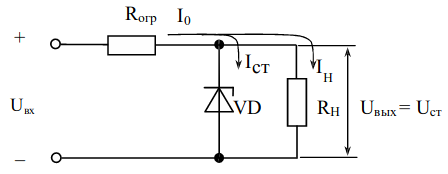

I_st_min=5e-3; %А
I_st_max=25e-3; %А
U_inp_min=20; %В
U_inp_max=30; %В
R_load = 2e+3; %Ом
U_st = 20; %В

Выберем средний ток стабилитрона из условия

I_st = (I_st_max+I_st_min)/2

I_st = 0.0150

Необходимая величина входного напряжения

U_inp = (U_inp_min + U_inp_max)/2

U_inp = 25

Ток нагрузки

I_load = U_st/R_load

I_load = 0.0100

При этом необходимая величина входного напряжения будет равна


$$R_{\mathrm{вх}} =U_{\mathrm{ст}} +R_{\mathrm{огр}} \left(I_Н +I_{\mathrm{ст}} \right)$$


Отсюда можно найти необходимую величину ограничительного резистора:


$$R_{\mathrm{огр}} =\frac{\left(U_{\textrm{вх}} -U_{\textrm{ст}} \right)}{I_н +I_{\mathrm{ст}} }$$


R_lim = (U_inp-U_st)/(I_load+I_st)

R_lim = 200

Границы допустимого диапазона изменения входного напряжения определяем, пользуясьвыражениями


$$U_{\mathrm{вх}\ldotp \mathrm{min}} =U_{\mathrm{ст}} +\left(I_{\mathrm{ст}\ldotp \mathrm{min}} +I_Н \right)R_{\mathrm{огр}}$$



$$U_{\textrm{вх}\ldotp \max } =U_{\textrm{ст}} +\left(I_{\textrm{ст}\ldotp \max } +I_Н \right)R_{\mathrm{огр}}$$


U_inp_min = U_st+(I_st_min+I_load)*R_lim

U_inp_min = 23

U_inp_max = U_st+(I_st_max+I_load)*R_lim

U_inp_max = 27

Сравним с заданным диапазоном изменения входного напряжения.Вывод: стабилизация напряжения осуществляется во всем диапазоне изменения входногонапряжения.

Задача №3

Пользуясь справочными данными, приведите семейство входных ивыходных характеристик БТ с ОЭ. В качестве независимых переменных используйте входное и выходное напряжение. Тип транзистора выберите согласно табл. 1.3 в соответствии с шифром. Поясните поведение входных и выходных характеристик транзистора.

Тип транзистора: КТ351А

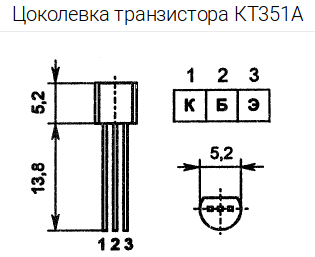

По справочнику установите максимально допустимые параметры БТ: постоянный ток коллектора $I_{K\ldotp \mathrm{max}}$;напряжение коллектор – эмиттер$U_{\mathrm{КЭ}\ldotp \mathrm{max}}$; мощность, рассеиваемую коллектором транзистора $P_{К,\mathrm{max}}$. Насемейство выходных характеристик нанесите границы области допустимых режимов работы.

Задайтесь положением рабочей точки и. пользуясь характеристиками, рассчитайте для нее значения h-параметров БТ. На основании полученных числовых значений параметров рассчитайте параметры Т-образной эквивалентной схемы транзистора и изобразите ее.

- Структура **p-n-p**

- Максимально допустимое (импульсное) напряжение коллектор-база **20 В**

- Максимально допустимое (импульсное) напряжение коллектор-эмиттер **15 В**

- Максимально допустимый постоянный(импульсный) ток коллектора **(400) мА**

- Максимально допустимая постоянная рассеиваемая мощность коллектора без теплоотвода (с теплоотводом) **0.3 Вт**

- Статический коэффициент передачи тока биполярного транзистора в схеме с общим эмиттером **20-80**

- Обратный ток коллектора **<=1 мкА**

- Граничная частота коэффициента передачи тока в схеме с общим эмиттером **=>200 МГц**

**Задача №4**

Усилительный каскад выполнен на ПТ КПЗ02Б в схеме с ОИ.

Рабочая точка ПТ задается напряжением источника питания $U_{\mathrm{ИП}} =10В$ и параметрами приведенными в табл. 1.4.	

- 	Нарисуйте принципиальную схему усилителя.	

- 	На семействе статических ВАХ транзистора постройте нагрузочную прямую и определите положение рабочей точки.	

- 	Для найденной рабочей точки определите сопротивление резистора в цепи истока $R_И$ и малосигнальные параметры $S$, $R_i$ и $\mu$.	

- 	Графоаналитическим методом определите параметры режима усиления $K_U$ и $P_{\mathrm{вых}}$ при амплитуде входного сигнала $U_{\textrm{зи}\ldotp m} =0\ldotp 25В$.

Исходные данные:

$R_C =0\ldotp 5e+3\;\mathrm{Ом}$;


$$I_c =\frac{U_{\mathrm{ИП}} }{R_C }=\frac{10В}{500}=20\mathrm{mA}$$


$U_{\mathrm{зи0}} =-1\ldotp 5\;В$;

1)

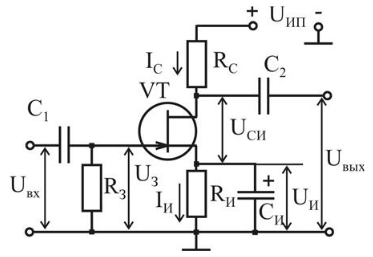

2)